%%%% MOSTANY LAB
%%%% IFU July 2022

%%%%%%%%% MODIFICABLE PARAMETERS %%%%%%%%%%%%
framerate=9.45  %% Change depending on the frame rate

framerate =          9.45


factorx=105;        % milliseconds per frame (depends on the frame rate)
onset1=0.2;              % Onset: 20% 
onset2=0.5;              % Onset: 50%
B_B=30;                 % Begin of baseline 
B_E=90;                 % End of baseline (seg 10 to seg 15.25)
NVC_B=91;               % Begin of NVC
NVC_E=140;               % End of NVC


%% Open all the .mat files in a folder and concatenate them in a matrix called Results. 
S = dir(fullfile(directory_name,'*.mat'));
C = cell(1,numel(S));
Z = load(fullfile(directory_name,S(1).name));
F = fieldnames(Z);
for k = 2:numel(S)
    T = load(fullfile(directory_name,S(k).name));
    for n = 1:numel(F)
        Z.(F{n}) = cat(2, Z.(F{n}), T.(F{n})); % pick a suitable dimension
    end
end
Results=Z.Results;

%% Introduce a first row in the matrix that corresponds with the time of the frame
time=[0];
for i=2:size(Results,1);
    time(i,1)=(time(i-1))+(1/framerate);
end
Results=cat(2,time,Results);
Results([1:5],:)=[];
Average=mean(Results(:,2:end),2);
Results=cat(2,Results,Average);

k=k+2;

k =     11


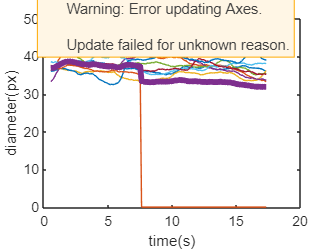

plot(Results(1:160,1),Results(1:160,2));
hold on
for r=3:k-1
    plot(Results(1:160,1),Results(1:160,r-1));
end
plot(Results(1:160,1),Results(1:160,end),'LineWidth',4);
hold off
xlabel('time(s)');
ylabel('diameter(px)');

axis([0 18 20 55]);

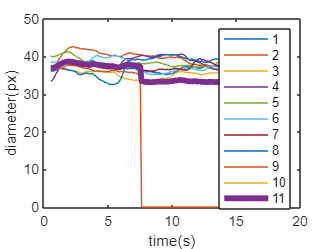

legend("1","2","3","4","5",'6','7','8','9','10','11','12');

Error using matlab.internal.editor.FigureManager.processPendingDrawnow
Error while evaluating HTMLCanvas ErrorCallback.



%Rename the file and save the plot and the matrix with the results
filename = S(1,1).name;
filename=replaceBetween(filename,'22_','PA','');
filename=strrep(filename,'_Diameter.mat','.png');
saveas(gcf,filename);


filename=strrep(filename,'.png','.mat');
save(filename,'Results');

% Automatic calculations of different parameters, based on the modificable
% parameters that are indicated on the top of the code

% Determine the values that will be used to average the values to percentage
Baseline=Results(B_B:B_E,end);                             
Average_Baseline=(mean(Baseline));          
Results_Baseline=Results(:,end)./Average_Baseline.*100;  % These are the relativized values of Results

filename=strrep(filename,'.mat','_perc.mat')  % Substitution of .mat by _perc.mat

filename = '3483_041322_PA1_perc.mat'

save(filename,"Results_Baseline")             % Save the Results in percentage

NVC_matrix=Results_Baseline(NVC_B:NVC_E,end); % NVC matrix   
[max_NVC,indexmax_NVC]=max(NVC_matrix);      % maximum peak (pixels in %, and index) of NVC
tmax_NVC=indexmax_NVC*factorx./1000;          % time maximum peak in seconds

onset1_value=onset1*(max_NVC-100)+100;       % value of onset1
onset1_index=find(NVC_matrix>onset1_value,1);% index where the first value of onset 1 is observed
onset1_time=onset1_index*factorx./1000;      % time to reach this onset (s)

onset2_value=onset2*(max_NVC-100)+100;       % value of onset1
onset2_index=find(NVC_matrix>onset2_value,1);% index where the first value of onset 1 is observed
onset2_time=onset2_index*factorx./1000;      % time to reach this onset

AUC=trapz(NVC_matrix);                       %area under the curve

halfdecaymatrix=Results_Baseline(indexmax_NVC:end,end);
halfdecay_index=find(max_NVC*0.5,1);
halfdecay_time=0.5291+(halfdecay_index+indexmax_NVC)*105;

Results_Baseline=Results_Baseline(12:150); % remove the first 11 rows of the matrix and the last 30
Dmax=max(Results_Baseline);                  % max value of the matrix
Dmin=min(Results_Baseline);                  % min value of the matrix
Rangemaxmin=Dmax-Dmin;                       % diff between max and minimimum

%Result display
results.max_NVC = max_NVC;
results.tmax_NVC = tmax_NVC;
results.onset20 = onset1_time

results = struct with fields:
        max_NVC: 100.44
       tmax_NVC: 0.105
        onset20: 0.105
        onset50: 0.105
            AUC: 4758.1
    Rangemaxmin: 7.3249
           Dmax: 102.77
           Dmin: 95.447


results.onset50 = onset2_time

results = struct with fields:
        max_NVC: 100.44
       tmax_NVC: 0.105
        onset20: 0.105
        onset50: 0.105
            AUC: 4758.1
    Rangemaxmin: 7.3249
           Dmax: 102.77
           Dmin: 95.447


results.halfdecay= halfdecay_time
results.AUC = AUC

results = struct with fields:
        max_NVC: 100.44
       tmax_NVC: 0.105
        onset20: 0.105
        onset50: 0.105
            AUC: 4758.1
    Rangemaxmin: 7.3249
           Dmax: 102.77
           Dmin: 95.447


results.Rangemaxmin=Rangemaxmin

results = struct with fields:
        max_NVC: 100.44
       tmax_NVC: 0.105
        onset20: 0.105
        onset50: 0.105
            AUC: 4758.1
    Rangemaxmin: 7.3249
           Dmax: 102.77
           Dmin: 95.447


results.Dmax=Dmax

results = struct with fields:
        max_NVC: 100.44
       tmax_NVC: 0.105
        onset20: 0.105
        onset50: 0.105
            AUC: 4758.1
    Rangemaxmin: 7.3249
           Dmax: 102.77
           Dmin: 95.447


results.Dmin=Dmin

results = struct with fields:
        max_NVC: 100.44
       tmax_NVC: 0.105
        onset20: 0.105
        onset50: 0.105
            AUC: 4758.1
    Rangemaxmin: 7.3249
           Dmax: 102.77
           Dmin: 95.447



format shortG
ResultsDisplay=[max_NVC;tmax_NVC;onset1_time;onset2_time;halfdecay_time;AUC;Rangemaxmin;Dmax;Dmin]

ResultsDisplay =        100.44
        0.105
        0.105
        0.105
       4758.1
       7.3249
       102.77
       95.447


%
